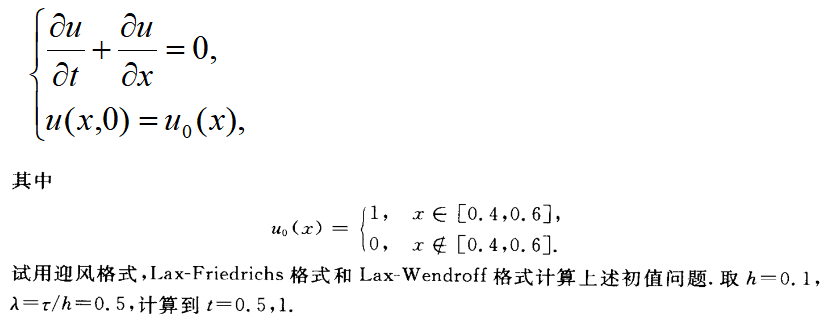

clc,clear,close all
a = 1;
tau = 0.05;
h = 0.1;

t = 0.5;
lambda = tau/h;
x0 = zeros(length(0:h:3),1);
x0(5:7) = 1;


迎风格式

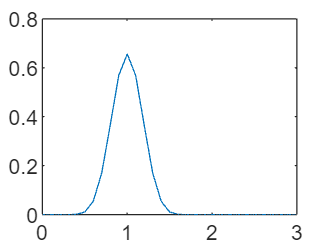

A1 = zeros(1,length(x0));
A2 = [diag(ones(1,length(x0)-1))*(1-lambda),zeros(length(x0)-1,1)];
A3 = [zeros(length(x0)-1,1),diag(ones(1,length(x0)-1))*lambda];
A = [A1;(A2+A3)];

n = t/tau;
x = A^n*x0;
plot(0:h:3,x)

Lax-Friedrichs 格式

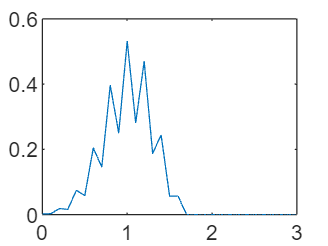

A1 = [0,1/4,zeros(1,length(x0)-2)];
A2 = [diag(ones(1,length(x0)-2))*3/4,zeros(length(x0)-2,2)];
A3 = [zeros(length(x0)-2,2),diag(ones(1,length(x0)-2))*1/4];
A4 = [zeros(1,length(x0)-2),3/4,0];
A = [A1;(A2+A3);A4];
n = t/tau;
x = A^n*x0;
plot(0:h:3,x)

Lax-Wendroff

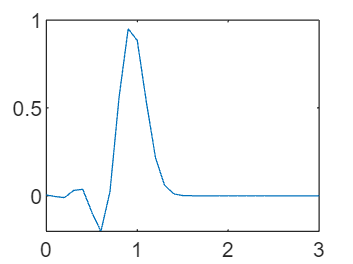

A1 = diag(ones(1,length(x0)))*(1-a^2*tau^2/h^2);
A2 = diag(ones(1,length(x0)-1),-1)*(a/2*tau/h+a^2/2*tau^2/h^2);
A3 = diag(ones(1,length(x0)-1),1)*(-a/2*tau/h+a^2/2*tau^2/h^2);
A = A1+A2+A3;
n = t/tau;
x = A^n*x0;
plot(0:h:3,x)